# Modeling Bird Migration as a Flow

**Raphaël Nussbaumer1,2,*, Silke Bauer1, Lionel Benoit2, Grégoire Mariethoz2, Felix Liechti1 & Baptiste Schmid**

1Swiss Ornithological Institute, Sempach, Switzerland

2Institute of Earth Surface Dynamics, University of Lausanne, Lausanne, Switzerland

This code accompagnies the publication:

     Modelling the flow of nocturnal bird migration with year-round European weather radar network

     Raphäel Nussbaumer, Lionel Benoit, Grégoire Mariethoz, Felix Liechti, Silke Bauer, Baptiste Schmid

     bioRxiv 2020.10.13.321844; doi: [https://doi.org/10.1101/2020.10.13.321844](https://doi.org/10.1101/2020.10.13.321844)

## Set-up

clear all;
if (exist('brewermap'))
    col2=colormap(brewermap([],'Paired'));
end
addpath('./functions/')

### Load data

load('data/Density_inference.mat','data');
load('data/Density_estimationMap','g');
load('data/Flight_estimationMap','guv');
load coastlines;

Compute basic grid data

dy = lldistkm([g.lat(1) g.lon(1)],[g.lat(2) g.lon(1)]); %dlat
dx = lldistkm([g.lat2D(:,1) g.lon2D(:,1)],[g.lat2D(:,1) g.lon2D(:,2)]); % dlon
area = repmat(dx*dy,1,g.nlon);

### **Build Grid**

gext.lat = fillmissing([nan(1,1) ;g.lat ;nan(1,1)],'linear');
gext.lon = fillmissing([nan(1,1); g.lon; nan(1,1)],'linear');
gext.nlat = numel(gext.lat);
gext.nlon = numel(gext.lon);
[gext.lat2D, gext.lon2D] = ndgrid(gext.lat,gext.lon);

gext.time = sort( [g.time; g.day-.5]);
 
gext.nt = numel(gext.time);
gext.day_id=nan(gext.nt,1);
gext.day_id(ismember(gext.time,g.time)) = g.day_id;
gext.day_id(isnan(gext.day_id)) = gext.day_id(find(isnan(gext.day_id))+1);
tmp=nan(g.nlm,gext.nt);
tmp(:,ismember(gext.time,g.time)) = g.NNT;
gext.NNT=nan(gext.nlat,gext.nlon,gext.nt);
gext.NNT(padarray(repmat(g.latlonmask,1,1,gext.nt),[1 1 0], false))=tmp;
gext.mask_day = logical(gext.NNT>-1 & gext.NNT<1);
gext.time_b=nan(gext.nt,1);
gext.time_b(ismember(gext.time,g.time)) = g.time_b;
gext.latlonmask = padarray(g.latlonmask,[1 1],false);

dxext = fillmissing([NaN;dx;NaN],'linear');
areaext = fillmissing(padarray(area,[1 1],nan),'linear',1);
areaext = fillmissing(areaext,'linear',2);

dt=15/60;

### Compute flight speed and density

vy = nan(g.nlat, g.nlon, gext.nt); vx=vy;
tmp = repmat(g.latlonmask,1,1,gext.nt); 
tmp(:,:,ismember(gext.time,g.day-.5))=false;
vy(tmp) = guv.v_est/1000*60*60; % m/s -> km/h (+) north, (-) south
vx(tmp) = guv.u_est/1000*60*60; % m/s -> km/h (+) east, (-) west


### Transect definition

transect_name={'North', 'East', 'Alpes', 'Spain' ,'Altlantic','England'};
transect(:,:,1)= [42 51 ; 43 82];
transect(:,:,2)= [20 45 ; 78 87];
transect(:,:,3)= [1 19 ; 40 84];
transect(:,:,4)= [1 9; 1 39];
transect(:,:,5) = [5 24; 1 18];
transect(:,:,6)= [25 43 ; 1 45];
sec_col={'r','b','y','g','c','k'};
cat_trans=zeros(gext.nlat,gext.nlon);
for i_s=1:numel(transect_name)
    cat_trans(transect(1,1,i_s):transect(1,2,i_s),transect(2,1,i_s):transect(2,2,i_s))=i_s;
end

## Flow Model

for ii=2:5

Load the 100 simulation

    load(['D:\Guests\rafnuss_at_gmail_com\tmp_BMM2018\Density_simulationMap_reassemble_' num2str(ii)]);

Compute for each realization

    nb_real = size(real_dens,4);
    
    Ts_day_landing=nan(g.nat,nb_real);
    Ts_day_takingoff=nan(g.nat,nb_real);
    Ts_Fout_day_entering=nan(g.nat,nb_real);
    Ts_Fout_day_leaving=nan(g.nat,nb_real);
    
    Fout_sec = nan(g.nat,numel(transect_name),2,nb_real);
    
    nightly_i_t=1:322;%52:55;
    nightly_W_takingoff=nan(g.nlat,g.nlon,numel(nightly_i_t),nb_real);
    nightly_W_landing = nightly_W_takingoff;
    nightly_dens = nightly_W_takingoff;
    
    seasonal_W_takingoff = nan(g.nlat,g.nlon,2,nb_real);
    seasonal_W_landing = seasonal_W_takingoff;
    
    
    for i_real = 1:nb_real
        tic
        disp(i_real)
        real_dens_tmp = real_dens(:,:,:,i_real);
    

remove for rain

        real_dens_tmp(g.rain>data.mask_rain_thr) = 0;
        
        rho = nan(g.nlat, g.nlon, gext.nt);
        rho(:,:,~ismember(gext.time,g.day-.5)) = real_dens_tmp;
        
        rho0 = rho;
        rho0(isnan(rho)) = 0; % bird/km^2

**Compute the Fluxes**

        Phiy_pad = padarray(rho .* vy .* repmat(dx,1,g.nlon,gext.nt) ,[1 0 0],nan); % bird/km^2 * km/h *km ->  bird/h
        Phix_pad = padarray(rho .* vx .* dy,[0 1 0],nan);
        
        Phiy_h = movmean(Phiy_pad,[0 1],1,'omitnan','Endpoints','discard');
        Phix_h = movmean(Phix_pad,[0 1],2,'omitnan','Endpoints','discard');
        
        Phiy_h_0=padarray(Phiy_h,[1 1 0],0);
        Phix_h_0=padarray(Phix_h,[1 1 0],0);
        
        Phiy_h_0(isnan(Phiy_h_0))=0;
        Phix_h_0(isnan(Phix_h_0))=0;
        
        dPhiy = diff(Phiy_h_0,1,1);
        dPhix = diff(Phix_h_0,1,2);
        
        F = (dPhiy + dPhix ).*dt; % bird/h * hr -> bird
        
        Fin = F;
        % Fin(~gext.mask_day)=0;
        Fin(repmat(~gext.latlonmask,1,1,gext.nt)) = 0;
        
        Fout = F;
        % Fout(gext.mask_day)=0;
        Fout(repmat(gext.latlonmask,1,1,gext.nt)) = 0;
        
        W = diff(rho0 .* area,1,3) + Fin(2:end-1,2:end-1,1:end-1);

**Aggregate the Fluxes**

Separate the landing/takingoff

        W_landing=W; W_takingoff=W;
        W_landing(W_landing>=0)=0;
        W_landing2 = W_landing; W_landing2(~gext.mask_day(2:end-1,2:end-1,1:end-1))=0;
        W_takingoff(W_takingoff<=0)=0;

 Separating entering and leaving

        Fout_leaving=Fout; Fout_entering=Fout;
        Fout_leaving(Fout_leaving>=0)=0;
        Fout_entering(Fout_entering<=0)=0;

Compute daily sum

        W_day_takingoff=nan(g.nlat,g.nlon,g.nat);
        W_day_landing=nan(g.nlat,g.nlon,g.nat);
        W_day_landing2=nan(g.nlat,g.nlon,g.nat);
        Fout_day_entering=nan(gext.nlat,gext.nlon,g.nat);
        Fout_day_leaving=nan(gext.nlat,gext.nlon,g.nat);
        for i_t=1:g.nat-1
            idt=gext.day_id(1:end-1)==i_t;
            W_day_takingoff(:,:,i_t)=nansum(W_takingoff(:,:,idt),3);
            W_day_landing(:,:,i_t)=nansum(W_landing(:,:,idt),3);
            W_day_landing2(:,:,i_t)=nansum(W_landing2(:,:,idt),3);
            Fout_day_entering(:,:,i_t)=nansum(Fout_entering(:,:,idt),3);
            Fout_day_leaving(:,:,i_t)=nansum(Fout_leaving(:,:,idt),3);
        end
        W_day_takingoff(W_day_takingoff==0)=nan;
        W_day_landing(W_day_landing==0)=nan;
        W_day_landing2(W_day_landing2==0)=nan;

Compute timeseries

        Ts_day_landing(:,i_real) = reshape(nansum(nansum(W_day_landing,1),2),1,[]);
        Ts_day_takingoff(:,i_real) = reshape(nansum(nansum(W_day_takingoff,1),2),1,[]);
        Ts_Fout_day_entering(:,i_real) = reshape(nansum(nansum(Fout_day_entering,1),2),1,[]);
        Ts_Fout_day_leaving(:,i_real) = reshape(nansum(nansum(Fout_day_leaving,1),2),1,[]);

Fluxes per transect

        for i_s=1:numel(transect_name)
            Fout_sec(:,i_s,1,i_real) = sum(reshape(Fout_day_entering(repmat(cat_trans==i_s,1,1,g.nat)),[],g.nat));
            Fout_sec(:,i_s,2,i_real) = sum(reshape(Fout_day_leaving(repmat(cat_trans==i_s,1,1,g.nat)),[],g.nat));
        end

Nighly Fluxes

        nightly_W_takingoff(:,:,:,i_real)=W_day_takingoff(:,:,nightly_i_t);
        nightly_W_landing(:,:,:,i_real)=W_day_landing2(:,:,nightly_i_t);
        for i_tt=1:numel(nightly_i_t)
            nightly_dens(:,:,i_tt,i_real)=nanmean(real_dens_tmp(:,:,nightly_i_t(i_tt)==g.day_id),3);
        end

Seasonal Flow : within

        id = g.day<datetime('2018-07-01');
        seasonal_W_takingoff(:,:,i_real,1)=nansum(W_day_takingoff(:,:,id),3);
        seasonal_W_landing(:,:,i_real,1)=nansum(W_day_landing2(:,:,id),3);
        %seasonal_W_W(:,:,i_real,1)=nansum(W_day_W(:,:,id),3);
        id = g.day>datetime('2018-07-01');
        seasonal_W_takingoff(:,:,i_real,2)=nansum(W_day_takingoff(:,:,id),3);
        seasonal_W_landing(:,:,i_real,2)=nansum(W_day_landing2(:,:,id),3);
        toc
    end
    nightly_W_takingoff(nightly_W_takingoff==0)=NaN;
    nightly_W_landing(nightly_W_landing==0)=NaN;
    nightly_dens(nightly_dens==0)=NaN;
    
    seasonal_W_landing(seasonal_W_landing==0)=NaN;
    seasonal_W_takingoff(seasonal_W_takingoff==0)=NaN;

**Save**

    save(['data/SinkSourceSim_' num2str(ii) '.mat'],'Ts_day_landing','nightly_i_t','Ts_day_takingoff','Ts_Fout_day_leaving','Ts_Fout_day_entering','Fout_sec','nightly_W_takingoff','nightly_W_landing','nightly_dens','seasonal_W_landing','seasonal_W_takingoff');
    %load('data/SinkSourceSim.mat')

end

## Load Sink-source data

load('data/SinkSourceSim_1.mat')
for i=2:5
    SSS = load(['data/SinkSourceSim_' num2str(i) '.mat']);
    Fout_sec = cat(4,Fout_sec,SSS.Fout_sec);
    Ts_Fout_day_entering = cat(2,Ts_Fout_day_entering,SSS.Ts_Fout_day_entering);
    Ts_Fout_day_leaving = cat(2,Ts_Fout_day_leaving,SSS.Ts_Fout_day_leaving);
    Ts_day_landing = cat(2,Ts_day_landing,SSS.Ts_day_landing);
    Ts_day_takingoff = cat(2,Ts_day_takingoff,SSS.Ts_day_takingoff);
    nightly_W_landing = cat(4,nightly_W_landing,SSS.nightly_W_landing);
    nightly_W_takingoff = cat(4,nightly_W_takingoff, SSS.nightly_W_takingoff);
    nightly_dens = cat(3,nightly_dens, SSS.nightly_dens);
    seasonal_W_landing = cat(3,seasonal_W_landing, SSS.seasonal_W_landing);
    seasonal_W_takingoff = cat(3,seasonal_W_takingoff, SSS.seasonal_W_takingoff);
end

Remove data of day where no data is available

knownday = ismember(datenum(g.day), unique(data.day(data.day_id)));
Ts_day_landing(~knownday,:)=nan;
Ts_day_takingoff(~knownday,:)=nan;
Ts_Fout_day_leaving(~knownday,:)=nan;
Ts_Fout_day_entering(~knownday,:)=nan;

## Method 

### Illustration of the fluxes

Choose a simulation

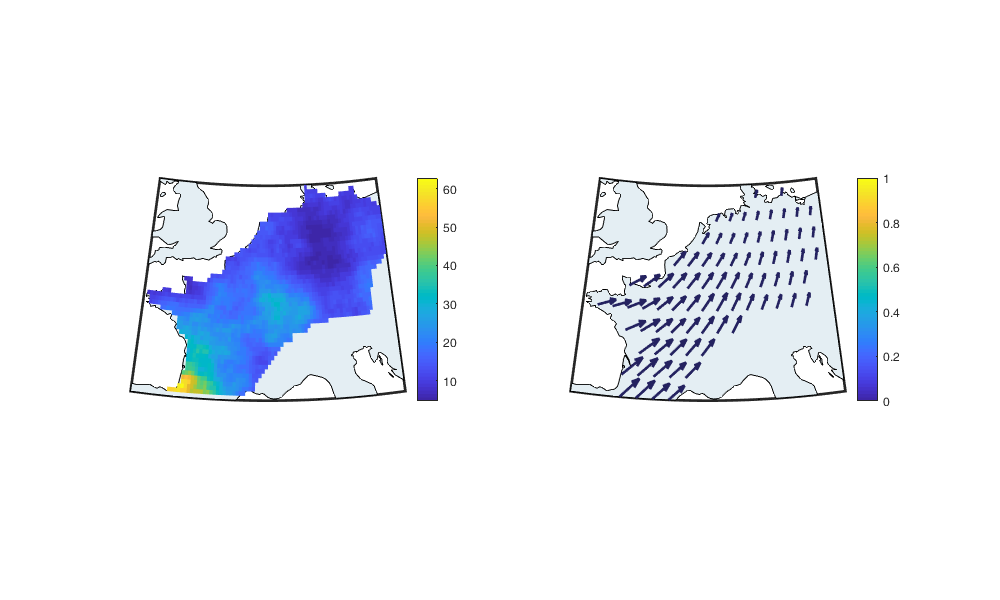

i_real = 56;
quiv_fac = 15;
i_t = 1;

figure('position',[0 0 1000 600]); 
subplot(1,2,1)
h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
W_tmp=nightly_dens(:,:,i_t,i_real); 
surfm(g.lat2D,g.lon2D,W_tmp ); colorbar; % caxis([0 50])

subplot(1,2,2)
h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [228 238 243]./255);
gu_tmp = nan(g.nlat, g.nlon); gv_tmp = nan(g.nlat, g.nlon);
gu_tmp(g.latlonmask)=nanmean(guv.u_est(:,nightly_i_t(i_t)==g.day_id),2);
gu_tmp(gu_tmp==0)=NaN;
gv_tmp(g.latlonmask)=nanmean(guv.v_est(:,nightly_i_t(i_t)==g.day_id),2);
gv_tmp(gv_tmp==0)=NaN;
h = quiverm(g.lat2D(1:5:end,1:5:end),g.lon2D(1:5:end,1:5:end),gu_tmp(1:5:end,1:5:end)/quiv_fac,gv_tmp(1:5:end,1:5:end)/quiv_fac,'-',0);
h(1).Color=[36 34 96]/255; h(2).Color=[36 34 96]/255; h(1).LineWidth=2; h(2).LineWidth=2;colorbar;

## Results

### Nightly migratory pulses and stopovers

Choose a simulation

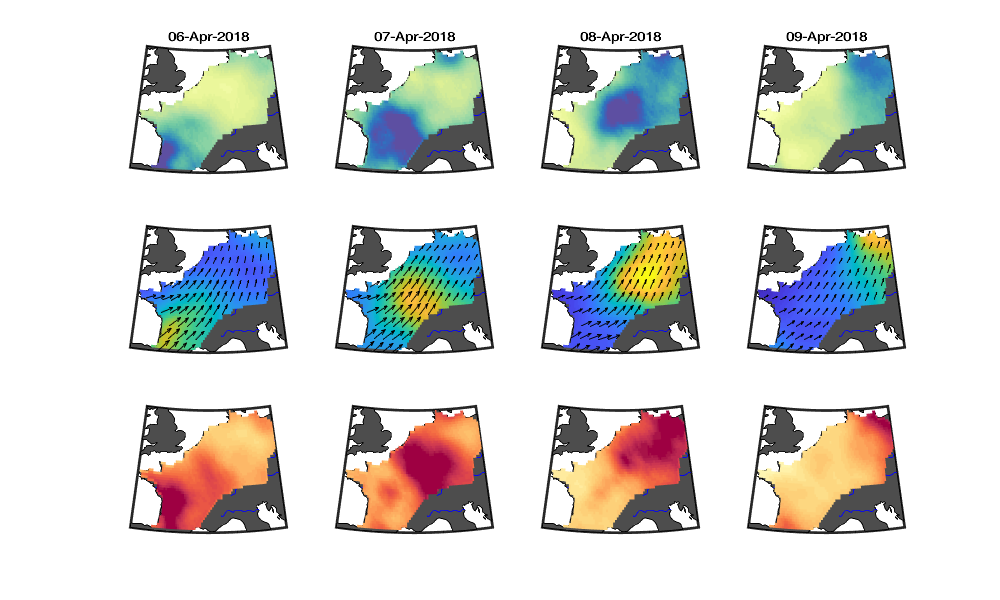

i_real = 56;
quiv_fac = 15;
figure('position',[0 0 1000 600]); 
nightly_i_t=52:55;
for i_tt=1:numel(nightly_i_t)
    for i2=1:3
        subplot(3,numel(nightly_i_t),numel(nightly_i_t)*(i2-1)+i_tt); hold on
        h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
        setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
        geoshow('landareas.shp', 'FaceColor', [77 77 77]./255); geoshow('worldrivers.shp','Color', 'blue')
        caxis([-70 70])
        if i2==1
            % W_tmp=nightly_W_takingoff(:,:,i_tt,i_real)./area;
            W_tmp=mean(nightly_W_takingoff(:,:,i_tt,:),4)./area;
            title(datestr(g.day(nightly_i_t(i_tt))))
            colormap(gca,brewermap([],'Spectral'))
        elseif i2==2
            % W_tmp=nightly_dens(:,:,i_tt,i_real); 
            W_tmp=mean(nightly_dens(:,:,i_tt,:),4); 
            caxis([0 40])
        elseif i2==3
            % W_tmp=nightly_W_landing(:,:,i_tt,i_real)./area;
            W_tmp=mean(nightly_W_landing(:,:,i_tt,:),4)./area;
             colormap(gca,brewermap([],'Spectral'))
        end
        surfm(g.lat2D,g.lon2D,W_tmp ); % colorbar 
        
        if i2==2
            gu_tmp = nan(g.nlat, g.nlon); gv_tmp = nan(g.nlat, g.nlon);
            gu_tmp(g.latlonmask)=nanmean(guv.u_est(:,nightly_i_t(i_tt)==g.day_id),2);
            gu_tmp(gu_tmp==0)=NaN;
            gv_tmp(g.latlonmask)=nanmean(guv.v_est(:,nightly_i_t(i_tt)==g.day_id),2);
            gv_tmp(gv_tmp==0)=NaN;
            quiverm(g.lat2D(1:5:end,1:5:end),g.lon2D(1:5:end,1:5:end),gu_tmp(1:5:end,1:5:end)/quiv_fac,gv_tmp(1:5:end,1:5:end)/quiv_fac,'k',0)
        end
    end
end    

**Export for Suppl. mat.**

quiv_fac = 15;
std_deg = 1;
ntab = 15;
B = fspecial('gaussian', [ntab*2+1 ntab*2+1], std_deg);

for i_tt=1:g.nat
    figure('position',[0 0 1000 400]); 
    for i2=1:3
        subplot(1,3,i2); hold on
        h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
        setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
        geoshow('landareas.shp', 'FaceColor', [77 77 77]./255); geoshow('worldrivers.shp','Color', 'blue')
        caxis([-70 70])
        if i2==1
            % W_tmp=nightly_W_takingoff(:,:,i_tt,i_real)./area;
            W_tmp=mean(nightly_W_takingoff(:,:,i_tt,:),4)./area;
            W_tmp=W_tmp
            title(datestr(g.day(nightly_i_t(i_tt))))
            colormap(gca,brewermap([],'Spectral'))
        elseif i2==2
            % W_tmp=nightly_dens(:,:,i_tt,i_real); 
            W_tmp=mean(nightly_dens(:,:,i_tt,:),4); 
            caxis([0 40])
        elseif i2==3
            % W_tmp=nightly_W_landing(:,:,i_tt,i_real)./area;
            W_tmp=mean(nightly_W_landing(:,:,i_tt,:),4)./area;
             colormap(gca,brewermap([],'Spectral'))
        end
        
        W_tmp2 = nanconv(W_tmp,B, 'nanout');
        surfm(g.lat2D,g.lon2D,W_tmp2 ); % colorbar 
        
        if i2==2
            gu_tmp = nan(g.nlat, g.nlon); gv_tmp = nan(g.nlat, g.nlon);
            gu_tmp(g.latlonmask)=nanmean(guv.u_est(:,nightly_i_t(i_tt)==g.day_id),2);
            gu_tmp(gu_tmp==0)=NaN;
            gv_tmp(g.latlonmask)=nanmean(guv.v_est(:,nightly_i_t(i_tt)==g.day_id),2);
            gv_tmp(gv_tmp==0)=NaN;
            quiverm(g.lat2D(1:5:end,1:5:end),g.lon2D(1:5:end,1:5:end),gu_tmp(1:5:end,1:5:end)/quiv_fac,gv_tmp(1:5:end,1:5:end)/quiv_fac,'k',0)
        end
    end
    saveas(gcf,['D:\Guests\rafnuss_at_gmail_com\switchdrive\Paper\BirdFlow\2_JRSI_review\SM\day_' num2str(i_tt) '.png'])
end 

### Year-round accumulation of migratory birds on the ground

Times serie daily

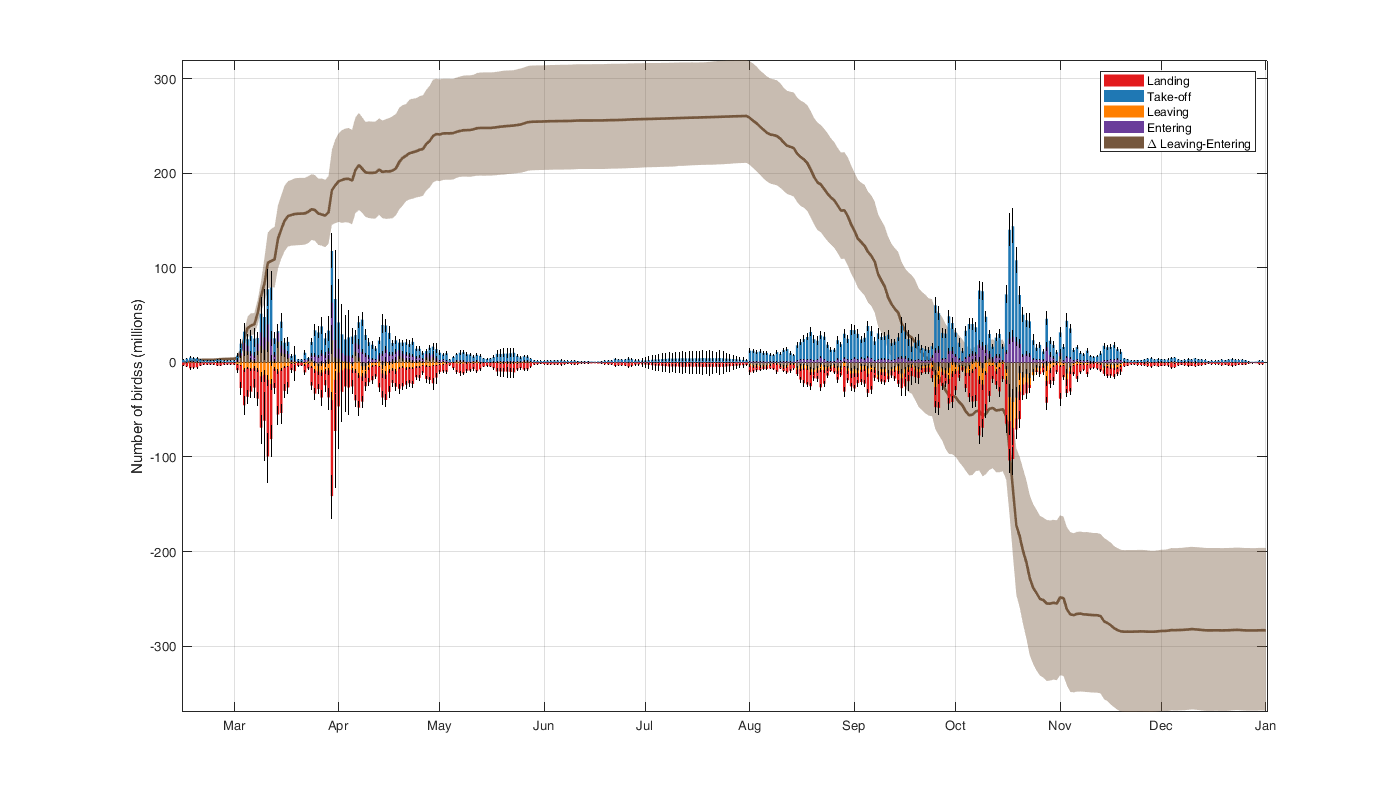

figure('position',[0 0 1400 800]); box on; grid on
hold on; ylabel('Number of birdss (millions)')

% fill(datenum([g.day(1); g.day; g.day(end)]),[0 cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan') 0],'k','FaceAlpha',0.2);
tmp =[quantile(cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan'),0.05,2) ; flipud(quantile(cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan'),0.95,2))];
fill(datenum([g.day; flipud(g.day)]),tmp,[117 87 61]/255,'FaceAlpha',0.4,'EdgeColor','none');
plot(datenum(g.day),mean(cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan'),2),'Color',[117 87 61]/255,'linewidth',2 ,'DisplayName','Cumulative \Delta takingoff/landing = # on the ground');
%plot(datenum(g.day),quantile(cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan'),0.05,2),'Color',[117 87 61]/255,'linewidth',1)
%plot(datenum(g.day),quantile(cumsum((Ts_Fout_day_leaving+Ts_Fout_day_entering)/1000000,'omitnan'),0.95,2),'Color',[117 87 61]/255,'linewidth',1)

tmp_TS = cat(3,Ts_day_landing,Ts_day_takingoff,Ts_Fout_day_leaving,Ts_Fout_day_entering,Ts_Fout_day_leaving+Ts_Fout_day_entering);
tmp_col = {col2(6,:), col2(2,:),col2(8,:), col2(10,:) [117 87 61]/255};
clear h
for i=1:size(tmp_TS,3)
    tmp = tmp_TS(:,:,i)/1000000;
    h(i)=bar(datenum(g.day),nanmean(tmp,2),'FaceColor',tmp_col{i});
    errorbar(datenum(g.day),nanmean(tmp,2),nanmean(tmp,2)-quantile(tmp,0.05,2),nanmean(tmp,2)-quantile(tmp,0.95,2),'LineStyle','none','Color','k','LineWidth',0.5,'CapSize',0);   
end
legend(h,{'Landing','Take-off','Leaving','Entering','\Delta Leaving-Entering'});
datetick('x'); axis tight; %legend([h2 h3 h4 h5 h6 h1]);

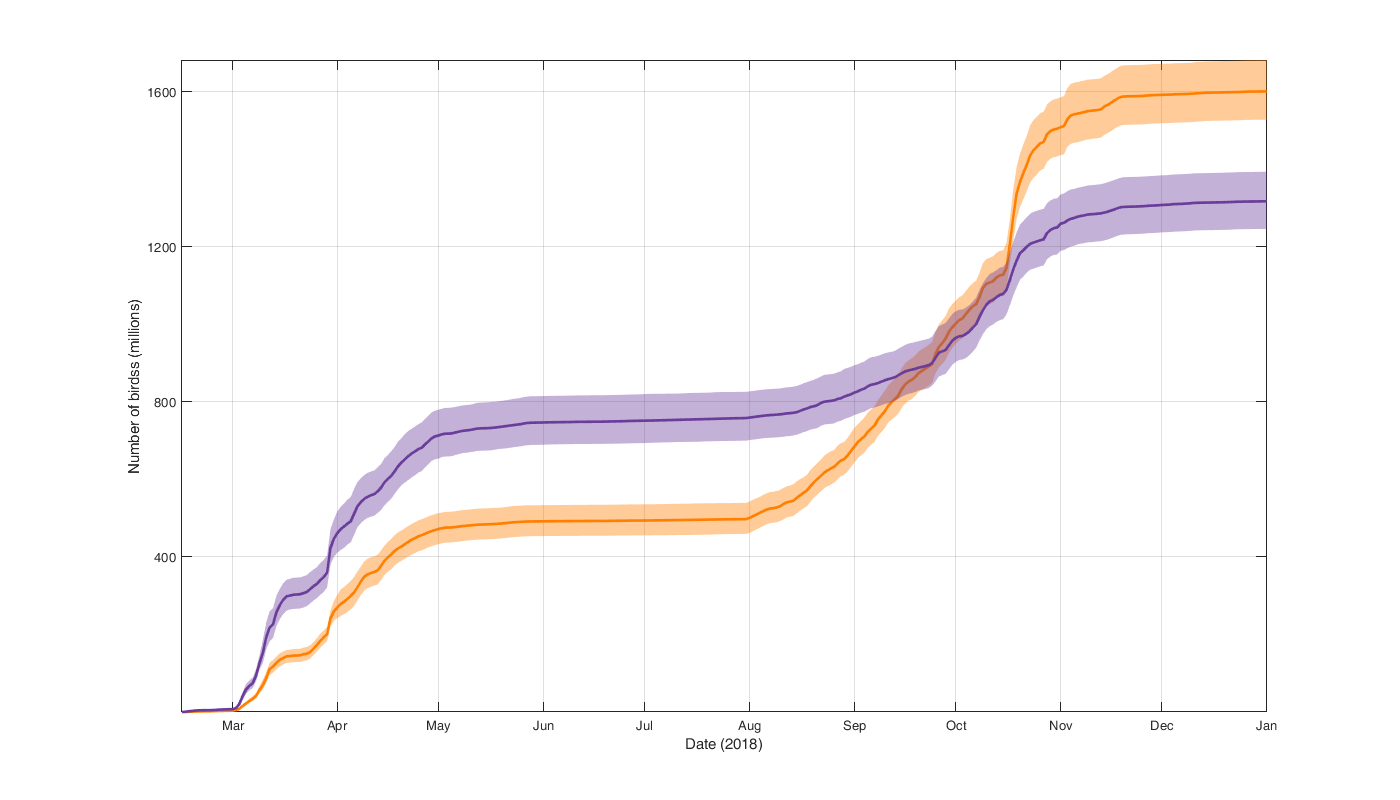

figure('position',[0 0 1400 800]);  box on; grid on
hold on; ylabel('Number of birdss (millions)')
%h1=fill(datenum([g.day ;flipud(g.day)]),-[cumsum((Ts.Fout.day.leaving)/1000000,'omitnan') fliplr(cumsum(-(Ts.Fout.day.entering)/1000000,'omitnan'))],'k','FaceAlpha',0.2,'DisplayName','Difference');
tmp =[quantile(cumsum(-(Ts_Fout_day_leaving)/1000000,'omitnan'),0.05,2) ; flipud(quantile(cumsum(-(Ts_Fout_day_leaving)/1000000,'omitnan'),0.95,2))];
fill(datenum([g.day; flipud(g.day)]),tmp,col2(8,:),'FaceAlpha',0.4,'EdgeColor','none');
plot(datenum(g.day),mean(cumsum(-(Ts_Fout_day_leaving)/1000000,'omitnan'),2),'Color',col2(8,:),'linewidth',2 ,'DisplayName','Cumulative Leaving');
tmp =[quantile(cumsum((Ts_Fout_day_entering)/1000000,'omitnan'),0.05,2) ; flipud(quantile(cumsum((Ts_Fout_day_entering)/1000000,'omitnan'),0.95,2))];
fill(datenum([g.day; flipud(g.day)]),tmp,col2(10,:),'FaceAlpha',0.4,'EdgeColor','none');
plot(datenum(g.day),mean(cumsum((Ts_Fout_day_entering)/1000000,'omitnan'),2),'Color',col2(10,:),'linewidth',2 ,'DisplayName','Cumulative Entering');
datetick('x'); xlabel('Date (2018)'); axis tight; yticks(0:400:1600) %legend([h2 h3 h1]);

**Statistics**

function to help display uncertainty

fmeanq5q90 = @(x) [num2str(round(mean(x))) 'M (' num2str(round(quantile(x,0.05))) '-' num2str(round(quantile(x,0.95))) ')'];

Maximum Number of bird in a night

[max_takeoff,tmp] = max(Ts_day_takingoff(g.day<datetime('15-July-2018'),:));
if ~all(diff(tmp)==0),   warning('Different day for max taking-off'); end

disp(['Maximum number of bird taking-off is: ' fmeanq5q90(max_takeoff/1000000) ' happening on the ' datestr(median(g.day(tmp))) '.'])

Maximum number of bird taking-off is: 118M (99-137) happening on the 30-Mar-2018.


[max_takeoff,tmp] = max(Ts_day_takingoff(g.day>datetime('15-July-2018'),:));
if ~all(diff(tmp)==0),   warning('Different day for max taking-off'); end

disp(['Maximum number of bird taking-off is: ' fmeanq5q90(max_takeoff/1000000) ' happening on the ' datestr(median(g.day(tmp)+sum(g.day<datetime('15-July-2018')))) '.'])

Maximum number of bird taking-off is: 148M (133-164) happening on the 17-Oct-2018.


How many night to reach 50% of all departure

tmp = Ts_day_takingoff(g.day<datetime('15-July-2018')& all(~isnan(Ts_day_takingoff),2),:);
tmp = sum( (cumsum(sort(tmp,'descend'),'omitnan') ./ nansum(tmp)) < .5);
disp(['50% of all bird taking-off in Spring happened in ' num2str(mean(tmp)) ' (SD=' num2str(std(tmp)) ') '])

50% of all bird taking-off in Spring happened in 19.12 (SD=0.78411) 


tmp = Ts_day_takingoff(g.day>datetime('15-July-2018')& all(~isnan(Ts_day_takingoff),2),:);
tmp=sum( (cumsum(sort(tmp,'descend'),'omitnan') ./ nansum(tmp)) < .5);
disp(['50% of all bird taking-off in Autumn happened in ' num2str(mean(tmp)) ' (SD=' num2str(std(tmp)) ') '])

50% of all bird taking-off in Autumn happened in 28.638 (SD=0.71832) 


General flow

tmp = cat(3,Ts_Fout_day_entering,Ts_Fout_day_leaving,Ts_day_landing,Ts_day_takingoff,Ts_Fout_day_entering+Ts_Fout_day_leaving)/1000000;
tmp2 = [reshape(mean(nansum(tmp),2),[],1)    reshape(mean(nansum(tmp(g.day<datetime('15-July-2018'),:,:)),2),[],1)    reshape(mean(nansum(tmp(g.day>datetime('15-July-2018'),:,:)),2),[],1)];
tmp2 = [tmp2 reshape(quantile(nansum(tmp(g.day<datetime('15-July-2018'),:,:)),.05,2),[],1)  reshape(quantile(nansum(tmp(g.day<datetime('15-July-2018'),:,:)),.95,2),[],1)  reshape(quantile(nansum(tmp(g.day>datetime('15-July-2018'),:,:)),.05,2),[],1) reshape(quantile(nansum(tmp(g.day>datetime('15-July-2018'),:,:)),.95,2),[],1)];
var_name = {'Fluxes','MeanTotal','MeanSpring','MeanAutumn','Q5Spring','Q95Spring','Q5Autumn','Q95Autumn'};
tmp2=round(tmp2);
accumt = table({'Entering','Leaving','Landing','Taking-off','Accumulation'}',tmp2(:,1),tmp2(:,2),tmp2(:,3),tmp2(:,4),tmp2(:,5),tmp2(:,6),tmp2(:,7),'VariableNames',var_name)

accumt = 5×8 table
        Fluxes        MeanTotal    MeanSpring    MeanAutumn    Q5Spring    Q95Spring    Q5Autumn    Q95Autumn
    ______________    _________    __________    __________    ________    _________    ________    _________

    'Entering'           1244          685           559          639          741         522          598  
    'Leaving'           -1544         -441         -1103         -470         -415       -1174        -1032  
    'Landing'           -4748        -2055         -2693        -2149        -1973       -2772        -2623  
    'Taking-off'         5049         1811          3237         1741         1886        3160         3321  
    'Accumulation'       -300          244      

Recrutement = Flux out/Flux in = Bird in + reproduction / Bird in

tmp3 = -nansum(tmp(g.day>datetime('15-July-2018'),:,5),1) ./ nansum(tmp(g.day<datetime('15-July-2018'),:,5),1);
disp(['Ratio of Aumtumn accumulation over spring accumulation: ' num2str(mean(tmp3)) ' (' num2str(quantile(tmp3,0.05)) '-' num2str(quantile(tmp3,0.95)) ')'])

Ratio of Aumtumn accumulation over spring accumulation: 2.2626 (1.7991-2.8133)


tmp3 = -nansum(tmp(g.day>datetime('15-July-2018'),:,4),1) ./ nansum(tmp(g.day<datetime('15-July-2018'),:,3),1);
disp(['Ratio of Aumtumn departure over spring arrival: ' num2str(mean(tmp3)) ' (' num2str(quantile(tmp3,0.05)) '-' num2str(quantile(tmp3,0.95)) ')'])

Ratio of Aumtumn departure over spring arrival: 1.5763 (1.4951-1.6481)


### Seasonal Flow: In and Out

Define transect name and color

transect_name={'North', 'East', 'Alpes', 'Spain' ,'Altlantic','England'};
transect_col = [[221 62 64];[124 22 48];[49 174 114];[41 102 140];[71 39 109];[246 167 86]]/255;

Sum seasonal flow per transect

Fout_sec_season=nan(numel(transect_name),4,size(Fout_sec,4));
Fout_sec_season(:,1,:)=nansum(Fout_sec(knownday&g.day<datetime('2018-07-01'),:,1,:),1);
Fout_sec_season(:,2,:)=nansum(Fout_sec(knownday&g.day<datetime('2018-07-01'),:,2,:),1);
Fout_sec_season(:,3,:)=nansum(Fout_sec(knownday&g.day>datetime('2018-07-01'),:,1,:),1);
Fout_sec_season(:,4,:)=nansum(Fout_sec(knownday&g.day>datetime('2018-07-01'),:,2,:),1);

Plot seasonal flow

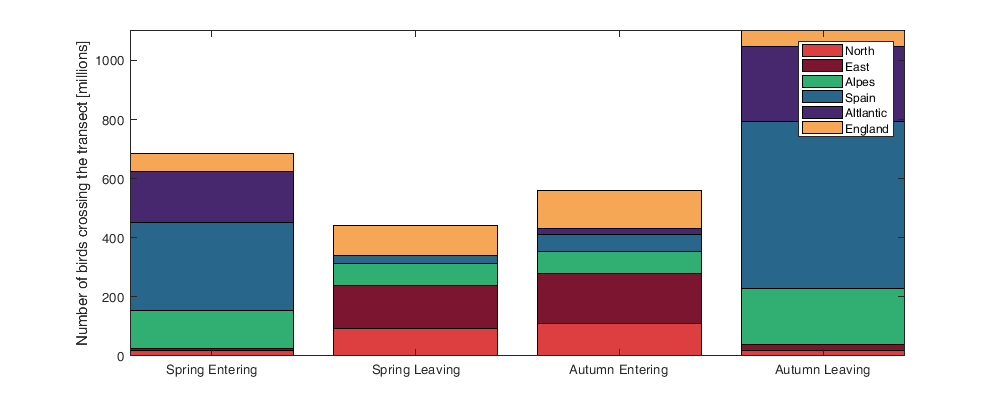

figure('position',[0 0 1000 400]); box on
b=bar(abs(mean(Fout_sec_season,3))'/1000000,'stacked'); axis tight
for k = 1:size(b,2), b(k).FaceColor = transect_col(k,:);end
xticklabels({'Spring Entering', 'Spring Leaving','Autumn Entering','Autumn Leaving'})
ylabel('Number of birds crossing the transect [millions]')
legend(transect_name)

Ratio of `entering/(entering+leaving)` per transect

table(transect_name',mean(Fout_sec_season(:,1,:)./sum(abs(Fout_sec_season(:,1:2,:)),2),3),mean(Fout_sec_season(:,3,:)./sum(abs(Fout_sec_season(:,3:4,:)),2),3),'VariableNames',{'Transect','Spring','Autumn'})

ans = 6×3 table
     Transect       Spring      Autumn 
    ___________    ________    ________

    'North'         0.16934     0.85292
    'East'         0.043072     0.89935
    'Alpes'         0.63104     0.28249
    'Spain'         0.91905    0.092167
    'Altlantic'     0.98783    0.068013
    'England'       0.38255     0.69263


Combining Spring entering and leaving and Autumn entering and leaving 

tmp = [sum(Fout_sec_season(:,1:2,:),2) sum(Fout_sec_season(:,3:4,:),2)]/1000000;

Spring and Autum (col) fluxes over the transects

var_name = {'Transect','MeanSpring','MeanAutumn','Q5Spring','Q95Spring','Q5Autumn','Q95Autumn','Ratio','Q5Ratio','Q95Ratio'};
table(transect_name',mean(tmp(:,1,:),3),mean(tmp(:,2,:),3),quantile(tmp(:,1,:),0.05,3),quantile(tmp(:,1,:),0.95,3),quantile(tmp(:,2,:),0.05,3),quantile(tmp(:,2,:),0.95,3),-mean(tmp(:,2,:)./tmp(:,1,:),3),-quantile(tmp(:,2,:)./tmp(:,1,:),0.05,3),-quantile(tmp(:,2,:)./tmp(:,1,:),0.95,3),'VariableNames',var_name)

ans = 6×10 table
     Transect      MeanSpring    MeanAutumn    Q5Spring    Q95Spring    Q5Autumn    Q95Autumn    Ratio     Q5Ratio    Q95Ratio
    ___________    __________    __________    ________    _________    ________    _________    ______    _______    ________

    'North'         -74.796        91.499      -82.244      -67.759      79.059       104.54     1.2269    1.4418      1.0432 
    'East'          -137.59        150.36      -156.61      -120.97       129.2       176.07     1.0991    1.3204     0.89218 
    'Alpes'           53.04       -114.49       43.379        63.28     -132.92      -96.589     2.1867    2.8269      1.6953 
    'Sp

Internal change

[
table(mean(sum(tmp([1 2 6],1,:),1),3),mean(sum(tmp([1 2 6],2,:)),3),quantile(sum(tmp([1 2 6],1,:)),0.05,3),quantile(sum(tmp([1 2 6],1,:)),0.95,3),quantile(sum(tmp([1 2 6],2,:)),0.05,3),quantile(sum(tmp([1 2 6],2,:)),0.95,3),-mean(sum(tmp([1 2 6],2,:))./sum(tmp([1 2 6],1,:)),3),quantile(-sum(tmp([1 2 6],2,:))./sum(tmp([1 2 6],1,:)),0.05,3),quantile(-sum(tmp([1 2 6],2,:))./sum(tmp([1 2 6],1,:)),0.95,3),'VariableNames',var_name(2:end));    
table(mean(sum(tmp(3:5,1,:),1),3),mean(sum(tmp(3:5,2,:)),3),quantile(sum(tmp(3:5,1,:)),0.05,3),quantile(sum(tmp(3:5,1,:)),0.95,3),quantile(sum(tmp(3:5,2,:)),0.05,3),quantile(sum(tmp(3:5,2,:)),0.95,3),-mean(sum(tmp(3:5,2,:))./sum(tmp(3:5,1,:)),3),-quantile(sum(tmp(3:5,2,:))./sum(tmp(3:5,1,:)),0.05,3),-quantile(sum(tmp(3:5,2,:))./sum(tmp(3:5,1,:)),0.95,3),'VariableNames',var_name(2:end));    
table(mean(sum(tmp(:,1,:),1),3),mean(sum(tmp(:,2,:)),3),quantile(sum(tmp(:,1,:)),0.05,3),quantile(sum(tmp(:,1,:)),0.95,3),quantile(sum(tmp(:,2,:)),0.05,3),quantile(sum(tmp(:,2,:)),0.95,3),-mean(sum(tmp(:,2,:))./sum(tmp(:,1,:)),3),-quantile(sum(tmp(:,2,:))./sum(tmp(:,1,:)),0.05,3),-quantile(sum(tmp(:,2,:))./sum(tmp(:,1,:)),0.95,3),'VariableNames',var_name(2:end))
]

ans = 3×9 table
    MeanSpring    MeanAutumn    Q5Spring    Q95Spring    Q5Autumn    Q95Autumn    Ratio     Q5Ratio    Q95Ratio
    __________    __________    ________    _________    ________    _________    ______    _______    ________

     -250.51        313.53      -273.47      -228.33      283.74       344.23     1.2551    1.0935      1.4241 
      494.12       -857.53       453.42       540.39     -916.72      -796.95     1.7407    1.9377      1.5452 
       243.6          -544       200.48       290.55     -610.04      -479.89     2.2626    2.8133      1.7991 


disp(['Density in Europe: ' num2str(mean(sum(tmp(3:5,2,:))/10/3*10)) ' birds/km^2'])

Density in Europe: -285.8428 birds/km^2


Sum of grouped transect

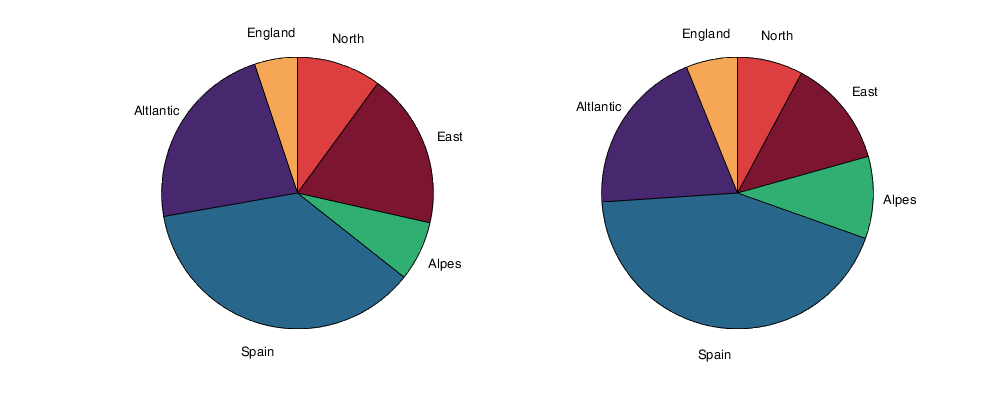

figure('position',[0 0 1000 400]);
subplot(1,2,1)
h=pie(flipud(abs(mean(tmp(:,1,:),3))),fliplr(transect_name));
set(findobj(h, 'Type', 'Patch'), {'FaceColor'}, flipud(mat2cell(transect_col, ones(size(transect_col,1),1), 3)))

subplot(1,2,2)
h=pie(flipud(abs(mean(tmp(:,2,:),3))),fliplr(transect_name));
set(findobj(h, 'Type', 'Patch'), {'FaceColor'}, flipud(mat2cell(transect_col, ones(size(transect_col,1),1), 3)))

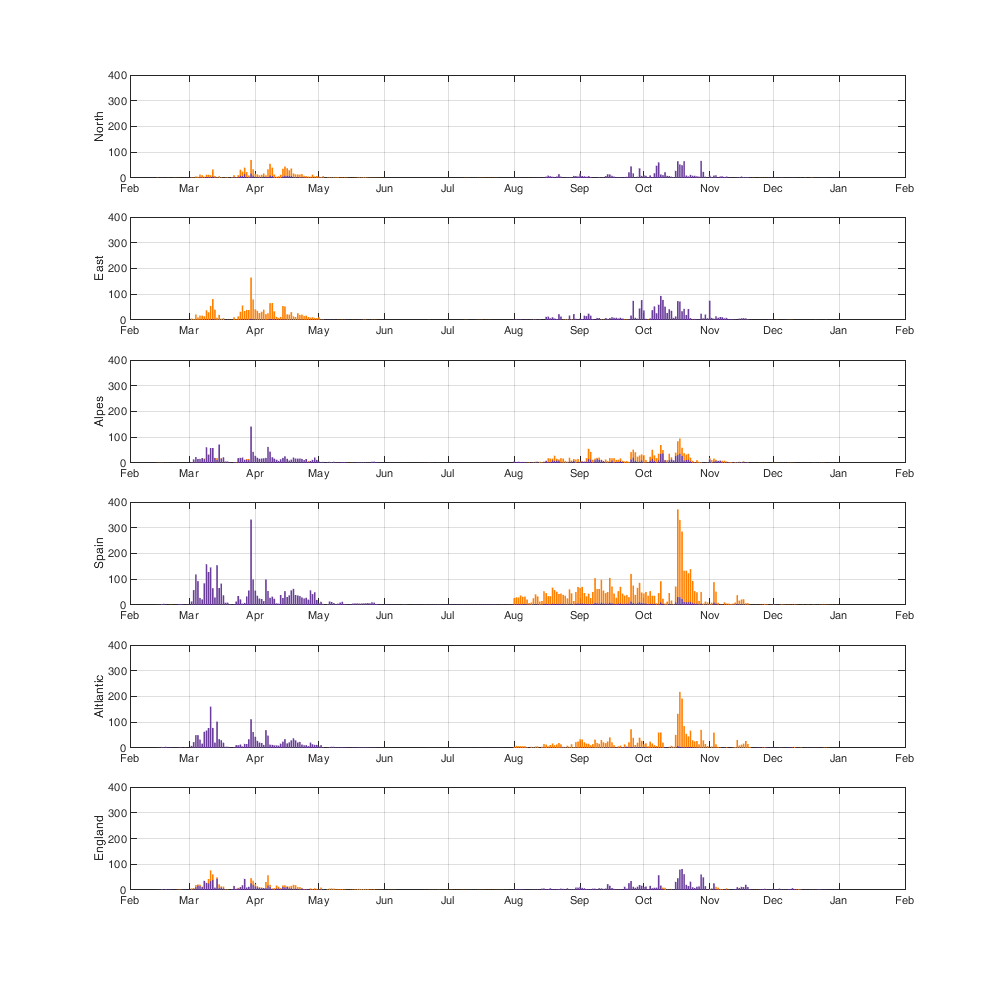

figure('position',[0 0 1000 1000]); 
for i_s=1:numel(transect_name)
    subplot(numel(transect_name),1,i_s); hold on;
    tmp = -Fout_sec(:,i_s,2,:)/100000;
    bar(datenum(g.day), mean(tmp,4),'FaceColor',col2(8,:));
    %errorbar(datenum(g.day),nanmean(tmp,4),nanmean(tmp,4)-quantile(tmp,0.05,4),quantile(tmp,0.95,4)-nanmean(tmp,4),'LineStyle','none','Color','k','LineWidth',0.5,'CapSize',0);
    tmp = Fout_sec(:,i_s,1,:)/100000;
    bar(datenum(g.day), mean(tmp,4),'FaceColor',col2(10,:));
    %errorbar(datenum(g.day),nanmean(tmp,4),nanmean(tmp,4)-quantile(tmp,0.05,4),quantile(tmp,0.95,4)-nanmean(tmp,4),'LineStyle','none','Color','k','LineWidth',0.5,'CapSize',0);
    ylabel(transect_name{i_s})
    ylim([0 400])
    yticks(0:100:400);box on; grid on;
    datetick('x');
    %set(gca, 'YScale', 'log')
end

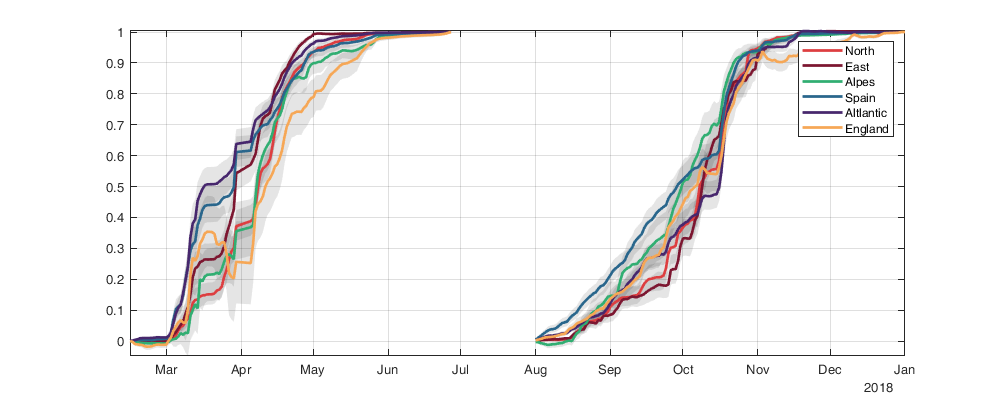

figure('position',[0 0 1000 400]); hold on;
tmp_sp = cumsum(sum(Fout_sec(knownday&g.day<datetime('2018-07-01'),:,:,:),3),1);
tmp_sp  = tmp_sp./tmp_sp(end,:,:,:);
h=fill([g.day(knownday&g.day<datetime('2018-07-01')); flipud(g.day(knownday&g.day<datetime('2018-07-01')))], ...
    [quantile(tmp_sp,.95,4); flipud(quantile(tmp_sp,.05,4))],...
    'k','FaceAlpha',0.1,'EdgeColor','none');
%for k = 1:size(h,1), h(k).FaceColor = transect_col(k,:);end
h=plot(g.day(knownday&g.day<datetime('2018-07-01')),mean(tmp_sp,4),'linewidth',2);
for k = 1:size(h,1), h(k).Color = transect_col(k,:);end
Fout_sec(end,:,:,:,:)=0; % error at the last day
tmp_au = cumsum(sum(Fout_sec(knownday&g.day>datetime('2018-07-01'),:,:,:),3),1);
tmp_au  = tmp_au./tmp_au(end,:,:,:);
h=fill([g.day(knownday&g.day>datetime('2018-07-01')); flipud(g.day(knownday&g.day>datetime('2018-07-01')))], ...
    [quantile(tmp_au,.95,4); flipud(quantile(tmp_au,.05,4))],...
    'k','FaceAlpha',0.1,'EdgeColor','none');
%for k = 1:size(h,1), h(k).FaceColor = transect_col(k,:);end
h=plot(g.day(knownday&g.day>datetime('2018-07-01')),nanmean(tmp_au,4),'linewidth',2);
for k = 1:size(h,1), h(k).Color = transect_col(k,:);end

axis tight; grid on; box on; legend(h, transect_name)

### **Seasonal Flow: Within the study area**

dy = lldistkm([g.lat(1) g.lon(1)],[g.lat(2) g.lon(1)]);
dx = lldistkm([g.lat2D(:,1) g.lon2D(:,1)],[g.lat2D(:,1) g.lon2D(:,2)]);
area = repmat(dx*dy,1,g.nlon);

Arrival/Departure over season

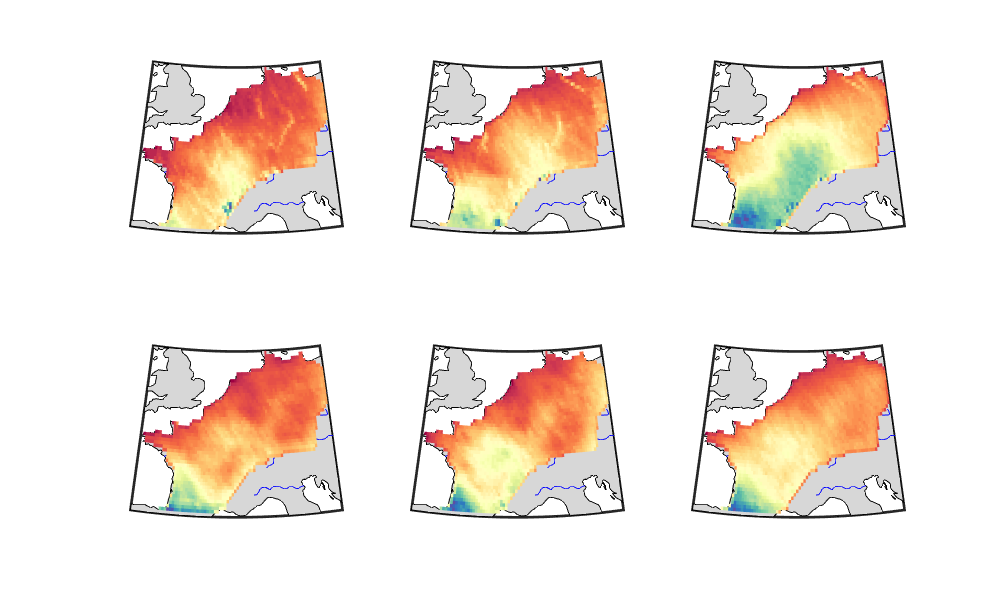

figure('position',[0 0 1000 600]); 
colormap(brewermap([],'Spectral'))
for i_s=1:2
    for i2=1:3
        subplot(2,3,(i_s-1)*3+i2); hold on
        h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
        setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
        geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue');
        %caxis([-4000 4000])
        if i2==1
            W_tmp=nanstd(seasonal_W_takingoff(:,:,:,i_s),[],3);
        elseif i2==2
            W_tmp=nanstd(seasonal_W_landing(:,:,:,i_s),[],3);
        elseif i2==3
            W_tmp=nanstd(seasonal_W_takingoff(:,:,:,i_s)+seasonal_W_landing(:,:,:,i_s),[],3);
         %   caxis([-2000 2000])
        end
        surfm(g.lat2D,g.lon2D,W_tmp./area ); 
        %plotm(data.lat,data.lon,'.k');  
    end
end